clear all

save_dir = "C:\Users\Personal\OneDrive\Documents\ONERA - Flow Stabilization\PYTHON\RL\Test\Cartpole_Controller\controller.mat";
save_dir_sos = "C:\Users\Personal\OneDrive\Documents\ONERA - Flow Stabilization\PYTHON\RL\Test\Cartpole_Controller\controller_sos.mat";
%%% SAVE IMAGES FOR DIFFERENT TESTING
save_dir_fig = "C:\Users\Personal\OneDrive\Documents\ONERA - Flow Stabilization\PYTHON\RL\Test\Cartpole_Controller\build_cartpole_minimal\Controller_Test";
folder_name = save_dir_fig;
if ~exist(folder_name, 'dir')
    mkdir(folder_name);
end

%IDEA: Primero, simular planta en open loop para revisar. Mi idea asería
%revisar en open loop para que las ecuaciones theta = 0 en el equilibrio
%inestable. 
%Constantes físicas
M = 1.0;      % cart mass [kg]
m = 0.1;      % pole mass [kg]
l = 0.5;      % pole half-length / COM dista|nce [m]
g = 9.81;     % gravity [m/s^2]
%Initial conditions
x0 = [0,0,deg2rad(15),0]';

%System dynamics : Linear Model
A = [0 1 0 0;
     0 0 -(m*g)/M 0;
     0 0 0 1;
     0 0 ((M+m)*g)/(l*M) 0];
B = [0; 1/M; 0; -1/(l*M)];
C = [0 0 1 0];
D = zeros(1,1);
syslin = ss(A,B,C,D);
%Weights LQR 
Q = diag([1,1,10,1]);
R = 0.1;
Klqr = lqr(syslin,Q,R);
%Observability
rank(obsv(A,C)); %Complete rank for C = [1 0 0 0];

G = ss(A,B,C,D);
G.InputName  = 'utotal';
G.OutputName = {'theta'};
s = tf('s');

% Weight on cart position x
Wx = 4.0*(s/2 + 1)/(s/0.05 + 1);

% Weight on cart velocity xdot
Wxdot = ss(0.5);

% Weight on pendulum angle theta
Wtheta = 20.0*(s/10 + 1)/(s/0.05 + 1);

% Weight on angular velocity thetadot
Wthetadot = ss(1.5);

% Weight on control effort u
Wu = 0.10*(s/40 + 1)/(s/400 + 1);

% Assign signal names
% Wx.InputName = 'x';
% Wx.OutputName = 'zx';
% 
% Wxdot.InputName = 'xdot';
% Wxdot.OutputName = 'zxdot';

Wtheta.InputName = 'theta';
Wtheta.OutputName = 'ztheta';

% Wthetadot.InputName = 'thetadot';
% Wthetadot.OutputName = 'zthetadot';

Wu.InputName = 'u';
Wu.OutputName = 'zu';
%%%
% Total physical force entering the cart-pole dynamics
SumU = sumblk('utotal = d + u');

% Build generalized plant
P = connect(G, Wtheta, Wu, SumU, ...
            {'d','u'}, ...
            {'ztheta','zu', ...
             'theta'});
%%%
nmeas = 1;   % y = [x; xdot; theta; thetadot]
ncont = 1;   % u = force

opts = hinfsynOptions('Display','off');

[Khinf, CL, gamma, info] = hinfsyn(P, nmeas, ncont, opts);

disp('================================================')

disp('H-infinity synthesis result')

H-infinity synthesis result


disp('================================================')

disp('Achieved gamma:')

Achieved gamma:


disp(gamma);

    0.1117




disp('Controller order:')

Controller order:


disp(order(Khinf));

     4




disp('Controller poles:')

Controller poles:


disp(pole(Khinf));

   1.0e+03 *

  -1.0170 + 0.8787i
  -1.0170 - 0.8787i
  -1.2375 + 0.0000i
  -0.0000 + 0.0000i



%Closed-Loop behavior for dynamical controller + linear model 
Khinf_ss = ss(Khinf);
[Ak,Bk,Ck,Dk] = ssdata(Khinf_ss);
Acl = [A + B*Dk*C, B*Ck;
        Bk*C, Ak];
eig(Acl);
save(save_dir, 'Ak', 'Bk', 'Ck', 'Dk','-v7')

%Discrete Controller
dt = 1e-3;
Ts = 1e-3; 
Khinf_disc = c2d(Khinf_ss,Ts,'zoh');
eig(Khinf_disc);
%Khinf_disc = minreal(Khinf_disc);
[Ad, Bd, Cd, Dd] = ssdata(Khinf_disc);
%Filter implentation K(z) = num/den
Khinf_disc_tf = tf(Khinf_disc);
K0_zpk = K0_sos2zpk(Ad,Bd,Cd,Dd,Ts,save_dir_sos);
%%%Matriz simulación discreta
Atot = K0_zpk.Ad_sos;
Btot = K0_zpk.Bd_sos;
Ctot = K0_zpk.Cd_sos;
Dtot = K0_zpk.Dd_sos;

[sos,g] = ss2sos(Ad,Bd,Cd,Dd); %PRIMER PASO FUNCIÓN, SOLO PARA COMPROBAR GANANCIA
[A2,B2,C2,D2] = sos2ss(sos,g); %REPRESENTACIÓN DISTINTA A LA MÍA, NO NECESARIAMENTE MAL. Dtot != 0 EN MI CASO

%%%LOAD PYTHON DATA%%%
cartpole_disc_SOS_csv = readtable("discrete_controller_SOS_signals.csv",VariableNamingRule='preserve');

%%%PLOTS TO COMPARE CLOSED-LOOP DYNAMICS FROM PYTHON AND MATLAB%%%
Tsim_cont = out.cartpole_cont1.Time;
theta_cont = out.cartpole_cont1.Data(:,1);
F_raw_cont = out.cartpole_cont1.Data(:,2); 
F_sat_cont = out.cartpole_cont1.Data(:,3); 
%%%
Tsim_disc = out.cartpole_disc1.Time;
theta_disc = out.cartpole_disc1.Data(:,1); 
F_raw_disc = out.cartpole_disc1.Data(:,2);
F_sat_disc = out.cartpole_disc1.Data(:,3);
%%% 
Tsim_cont_csv = cartpole_cont_csv.t;
theta_cont_csv = cartpole_cont_csv.theta;
F_raw_cont_csv = cartpole_cont_csv.u_raw_0;
F_sat_cont_csv = cartpole_cont_csv.u_sat_0;
%%%
Tsim_disc_csv = cartpole_disc_csv.t;
theta_disc_csv = cartpole_disc_csv.theta;
F_raw_disc_csv = cartpole_disc_csv.u_raw_0;
F_sat_disc_csv = cartpole_disc_csv.u_sat_0;

%%%ANÁLISIS SOS
%%%
Tsim_disc_SOS = out.cartpole_SOS.Time;
theta_disc_SOS = out.cartpole_SOS.Data(:,1); 
F_raw_disc_SOS = out.cartpole_SOS.Data(:,2);
F_sat_disc_SOS = out.cartpole_SOS.Data(:,3);
%%%
Tsim_disc_SOS_csv = cartpole_disc_SOS_csv.t;
theta_disc_SOS_csv = cartpole_disc_SOS_csv.theta;
F_raw_disc_SOS_csv = cartpole_disc_SOS_csv.u_raw_0;
F_sat_disc_SOS_csv = cartpole_disc_SOS_csv.u_sat_0;

clf
%%%COMPARISON PLOTS : CONTINUOUS DYNAMICS
plot(Tsim_cont,theta_cont,Color="b",LineWidth=2)
xlabel('t(s)', Interpreter='latex')
ylabel('$\theta$ (rad)', Interpreter="latex")
hold on 
plot(Tsim_cont_csv,theta_cont_csv,Color="r",LineWidth=2,LineStyle="--")
grid on
legend({'Simulation: Matlab','Implementation: Python'})
xlim([0 Tsim_cont(end)])
hold off
sgtitle(sprintf('Continuous) Cartpole + Controller:  $\\theta_0 = %.2g$, $dt = %.1e$, $T_s = %.e$',x0(3), dt, Ts), ...
    'Interpreter', 'latex')
%%%SAVE IMAGE 
filename = fullfile(folder_name, 'closed_loop_continuous_Hinf_SOS.png');
exportgraphics(gcf, filename, 'Resolution', 300)

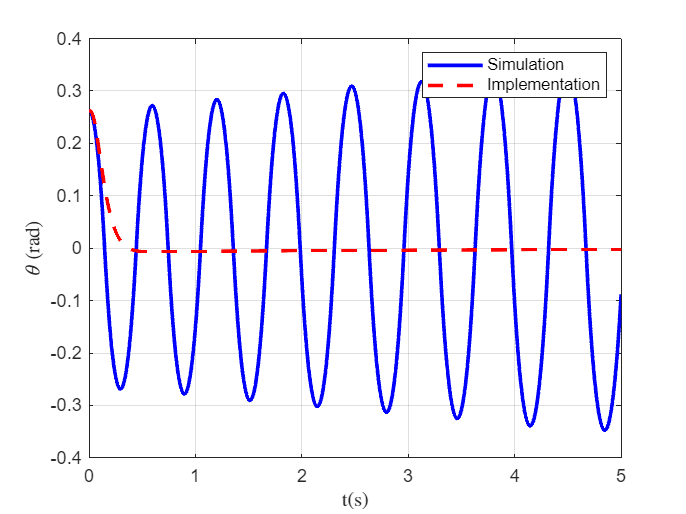

clf
%%%COMPARISON PLOTS : DISCRETE DYNAMICS
plot(Tsim_disc_SOS,theta_disc_SOS,Color="b",LineWidth=2)
xlabel('t(s)', Interpreter='latex')
ylabel('$\theta$ (rad)', Interpreter="latex")
hold on 
plot(Tsim_disc_SOS_csv,theta_disc_SOS_csv,Color="r",LineWidth=2,LineStyle="--")
grid on
legend({'Simulation','Implementation'})
xlim([0 Tsim_disc_SOS(end)])
hold off
%%%SAVE IMAGE 
filename = fullfile(folder_name, 'closed_loop_Hybrid_Hinf_SOS.png');
exportgraphics(gcf, filename, 'Resolution', 300)

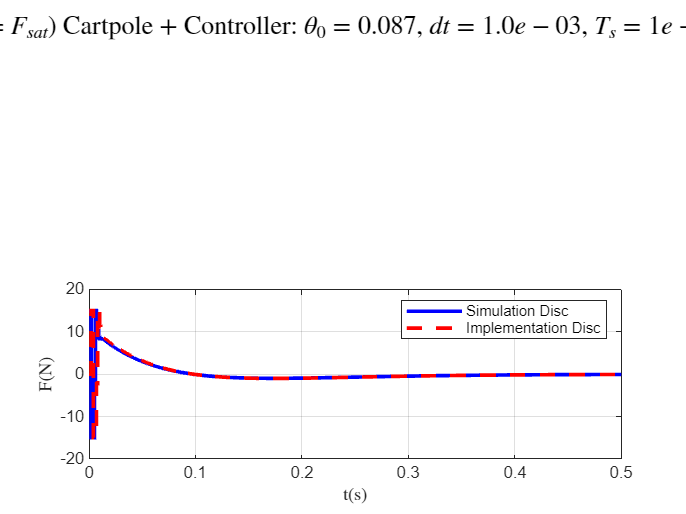

clf
%%COMPARISON PLOTS
subplot(2,1,1)
plot(Tsim_cont,F_sat_cont,Color="b",LineWidth=2)
xlabel('t(s)', Interpreter='latex')
ylabel("F(N)", Interpreter="latex")
hold on 
plot(Tsim_cont_csv,F_sat_cont_csv,Color="r",LineWidth=2,LineStyle="--")
grid on
legend({'Simulation Cont','Implementation Cont'})
xlim([0 0.5])
hold off
%%
subplot(2,1,2)
stairs(Tsim_disc,F_sat_disc,Color="b",LineWidth=2)
xlabel('t(s)', Interpreter='latex')
ylabel("F(N)", Interpreter="latex")
hold on 
stairs(Tsim_disc_csv,F_sat_disc_csv,Color="r",LineWidth=2,LineStyle="--")
grid on
legend({'Simulation Disc','Implementation Disc'})
xlim([0 0.5])
hold off
sgtitle(sprintf('(u = $F_{sat}$) Cartpole + Controller:  $\\theta_0 = %.2g$, $dt = %.1e$, $T_s = %.e$',x0(3), dt, Ts), ...
    'Interpreter', 'latex')
%%%SAVE IMAGE 
filename = fullfile(folder_name, 'closed_loop_SatForce_Hinf_SOS.png');
exportgraphics(gcf, filename, 'Resolution', 300)